% Load in a real world dataset
data = readtable("C:\Users\Ramkumar K R\OneDrive\Desktop\SEM-1 PROJECTS\MFC\diabetes.csv");

% Extracting the numeric data (assuming all columns are numeric)
numericData = data{:, :};

% Standardize the data
numericData = (numericData - mean(numericData)) ./ std(numericData);

% Perform PCA
[coeff, score, ~, ~, explained, mu] = pca(numericData)

coeff =     0.2160    0.5274    0.1645    0.1609    0.2118   -0.4568    0.0785   -0.5406    0.2651
    0.4368    0.0956   -0.3914   -0.3271    0.1088    0.3827   -0.2080    0.0252    0.5811
    0.3005    0.0463    0.6297    0.0111   -0.0594    0.6079    0.3267   -0.1628   -0.0683
    0.3073   -0.4484    0.2943    0.0740    0.1718   -0.3980    0.2820    0.4349    0.3948
    0.3363   -0.3553   -0.1417   -0.0976    0.6504   -0.0087   -0.0822   -0.2688   -0.4785
    0.3973   -0.2103    0.2519   -0.1632   -0.5275   -0.2410   -0.5725   -0.1665   -0.1264
    0.2376   -0.1752   -0.2853    0.8735   -0.1566    0.1716   -0.0572   -0.0932    0.0496
    0.2787    0.5332    0.1261    0.1711    0.2043    0.0011   -0.2994    0.6149   -0.2888
    0.4157    0.1548   -0.3946   -0.1817   -0.3779   -0.1714    0.5804    0.0683   -0.3176


score =     1.7558    1.1110   -0.2087    0.3335   -0.4814   -0.4327    0.4574    1.1237    0.4936
   -1.5064   -0.5590    0.6502    0.2298    0.0049   -0.1192    0.3662    0.8519    0.0313
    0.6504    1.9283   -2.0064   -0.0261   -0.2339    0.6736    0.7210   -0.7928    1.0630
   -1.5864   -1.0644    0.4741   -0.5803    0.2972   -0.0709    0.3445   -0.0306   -0.2408
    2.4818   -2.3580   -2.9236    3.9340   -1.5653   -0.2003   -0.8146    0.3984   -0.2490
   -1.4427    1.0547    0.2777   -0.4157    0.1453    0.6371    0.0041   -0.6124    0.1816
   -0.5067   -0.6259   -0.3915   -0.4892   -0.4402   -1.6058    1.2210    0.3543   -0.8023
   -1.8674    1.3889   -1.5165   -0.6010    0.0485   -2.7079   -1.7893   -1.0312    0.6768
    3.4935   -0.8620   -1.2148   -1.9023    3.0933    0.1948    0.0307    1.1811   -1.0245
   -0.6137    3.6830   -0.3850    0.2280    1.6195    1.4705    2.8462    0.6582   -0.3364


explained =    26.1389
   19.7146
   12.4469
    9.7995
    9.3847
    8.1652
    5.4269
    4.6465
    4.2768


mu = 1.0e-15 *

    0.0012   -0.0093    0.0069    0.0763    0.0833   -0.6245   -0.1128    0.1804    0.1434



% Plot the 2D data in terms of the first two principal components
figure;
scatter(score(:, 1), score(:, 2), 20, 'b'); % Original data in 2D PCA space
hold on;

% Plot the principal component line using reconstructed data points
% Project data onto the first principal component and reconstruct
pc1_projection = score(:, 1);
reconstructed_data1 = pc1_projection * coeff(:, 1)' + mu

reconstructed_data1 =     0.3793    0.7669    0.5275    0.5395    0.5905    0.6977    0.4172    0.4893    0.7298
   -0.3254   -0.6579   -0.4526   -0.4629   -0.5067   -0.5986   -0.3580   -0.4198   -0.6262
    0.1405    0.2841    0.1954    0.1999    0.2187    0.2584    0.1546    0.1812    0.2703
   -0.3427   -0.6929   -0.4766   -0.4875   -0.5335   -0.6303   -0.3770   -0.4420   -0.6594
    0.5361    1.0839    0.7457    0.7626    0.8347    0.9861    0.5898    0.6916    1.0315
   -0.3116   -0.6301   -0.4335   -0.4433   -0.4852   -0.5732   -0.3428   -0.4020   -0.5997
   -0.1095   -0.2213   -0.1522   -0.1557   -0.1704   -0.2013   -0.1204   -0.1412   -0.2106
   -0.4034   -0.8156   -0.5611   -0.5738   -0.6281   -0.7420   -0.4438   -0.5204   -0.7762
    0.7546    1.5258    1.0496    1.0735    1.1750    1.3881    0.8302    0.9735    1.4521
   -0.1326   -0.2680   -0.1844   -0.1886   -0.2064   -0.2439   -0.1458   -0.1710   -0.2551



pc2_projection = score(:,2);
reconstructed_data2 = pc2_projection * coeff(:,2)' + mu;

% Transform reconstructed data to 2D PCA space
reconstructed_data_pca1 = (reconstructed_data1 - mean(numericData)) * coeff(:, 1:2)

reconstructed_data_pca1 =     1.7558    0.0000
   -1.5064   -0.0000
    0.6504    0.0000
   -1.5864   -0.0000
    2.4818    0.0000
   -1.4427   -0.0000
   -0.5067   -0.0000
   -1.8674   -0.0000
    3.4935    0.0000
   -0.6137   -0.0000


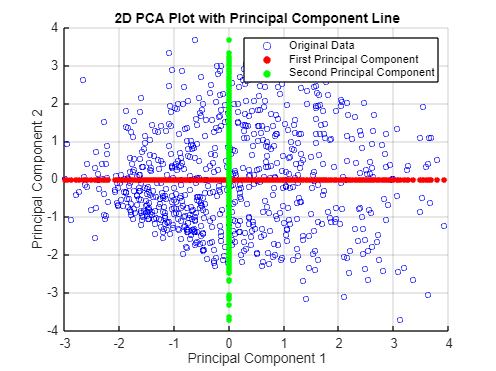

reconstructed_data_pca2 = (reconstructed_data2- mean(numericData)) * coeff(:, 1:2);
% Plot the line for the first principal component direction
scatter(reconstructed_data_pca1(:, 1), reconstructed_data_pca1(:, 2), 20, 'r', 'filled');
hold on
scatter(reconstructed_data_pca2(:, 1), reconstructed_data_pca2(:, 2), 20, 'g', 'filled');

% Formatting the plot
xlabel('Principal Component 1');
ylabel('Principal Component 2');
title('2D PCA Plot with Principal Component Line');
xlim([-3 4])
ylim([-4 4])
legend({'Original Data', 'First Principal Component', 'Second Principal Component'});
grid on;
hold off;


% Displying the variance onto the original data.
disp('Variance explained by each component (%):');

Variance explained by each component (%):


disp(explained);

   26.1389
   19.7146
   12.4469
    9.7995
    9.3847
    8.1652
    5.4269
    4.6465
    4.2768

